%% Lab 3+4: Final Simulation with Preamble Synchronization
% This script demonstrates realistic frame synchronization using a Preamble.
% We do NOT use the payload to calculate delay, only the known header.

clear; close all; clc;
load('my_filter_coeffs_FIR.mat');
%% 1. Parameters
M = 4; 
Rs = 3.84e6; 
Ns = 64; 
Vd = 1.0;

% --- Sample Rate Matching ---
% Ensure Fs_analog is an integer multiple of Digital Fs (Rs*Ns)


Fs_analog = 4500e6; 
fc = 1950e6; 

fprintf('System Configuration:\n');

System Configuration:


fprintf('  Analog Rate : %.2f MHz\n', Fs_analog/1e6);

  Analog Rate : 4500.00 MHz



%% 2. Data Generation (Updated with Barker Sequence)

% --- A. Design Robust Preamble (Barker Code) ---
% Barker-13 Code: Mathematically optimal for autocorrelation sidelobe suppression.
barker13 = [1 1 1 1 1 -1 -1 1 1 -1 1 -1 1];

% Repeat 4 times to increase length (13 * 4 = 52 symbols).
% Repetition increases the energy of the cross-correlation peak, 
% making it robust against high noise (e.g., SNR = 1).
seq_binary = [barker13, barker13, barker13, barker13]; 

% --- B. Map to M-ASK Extremes (High Energy) ---
% Instead of mapping to random intermediate symbols, we map the Barker sequence
% to the "Extreme Voltage Levels" of the M-ASK constellation to maximize energy.
% Mapping Rules:
%   Binary  1 -> Symbol (M-1)  (e.g., for M=4, corresponds to 3, i.e., +1.5V)
%   Binary -1 -> Symbol 0      (e.g., for M=4, corresponds to 0, i.e., -1.5V)

preamble = zeros(1, length(seq_binary));

% Apply Mapping Logic
preamble(seq_binary == 1)  = M - 1; % Map to Highest Level
preamble(seq_binary == -1) = 0;     % Map to Lowest Level

preamble_len = length(preamble); % Update length variable

% --- C. Generate Payload (Random) ---
payload_len = 100000;
payload = randi([0 M-1], 1, payload_len);

% --- D. Construct Frame ---
tx_frame = [preamble, payload];

fprintf('Robust Preamble Generated: Length %d (Barker-13 x4)\n', preamble_len);

Robust Preamble Generated: Length 52 (Barker-13 x4)



%% 3. Transmitter
disp('--- Transmitter ---');

--- Transmitter ---


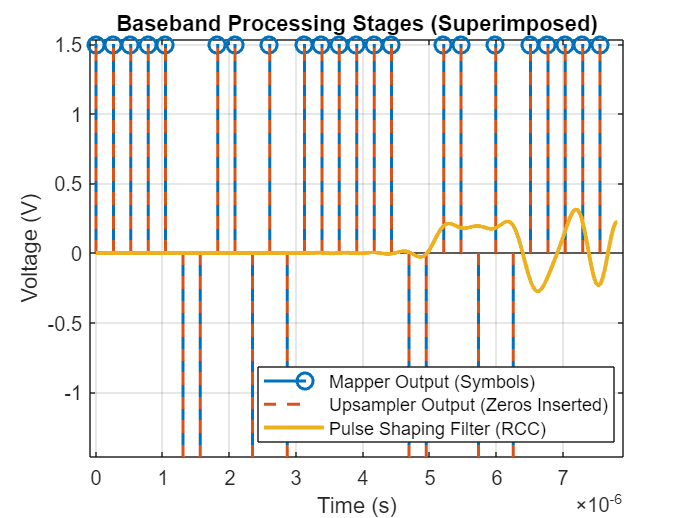

tx = Transmitter(M, Rs, fc, Vd, 'RCC'); 

% Manually inject our constructed frame into the transmitter
tx.symbols = tx_frame; 

% Continue with processing
tx.do_mapping();
tx.do_upsampling(Ns);
tx.do_pulse_shaping();
tx.do_dac(Fs_analog);
tx.do_modulation();

s_t = tx.modulation.signal;
t_axis = tx.modulation.time;

tx.plot_constellation();
tx.plot_baseband_signals(30);

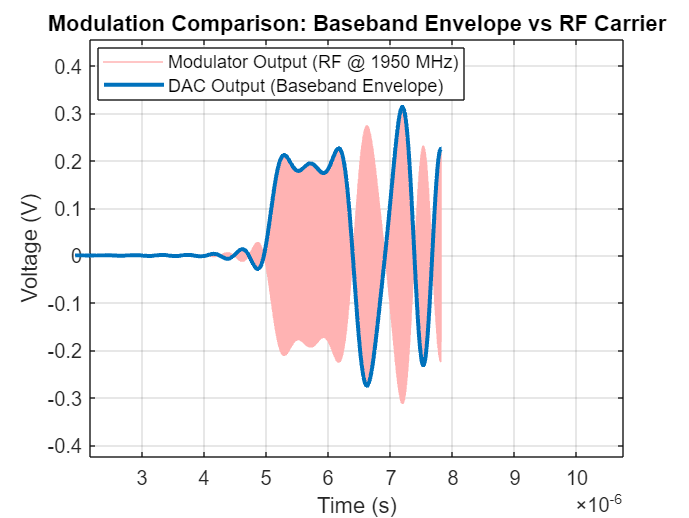

view_time = 30 * (1/Rs); 
tx.plot_modulator_output(view_time);

%% 4. Channel
disp('--- Channel ---');

--- Channel ---


% Add noise.
target_snr_db = 20;
process_gain = 10 * log10(Fs_analog/tx.Rs);
input_snr = target_snr_db - process_gain;
r_t = awgn(s_t, input_snr, 'measured');

%% 5. Receiver (Filter & Detection)
disp('--- Receiver ---');

--- Receiver ---



% --- Filter Loading ---
% Check for exported fdatool coefficients
if exist('Num', 'var') 
    b_coeff = Num;
    
    if exist('Den', 'var')
        disp('Loading IIR coefficients from Workspace...');
        a_coeff = Den;
        rx = Receiver(M, Rs, fc, Vd, Ns, b_coeff, a_coeff);     
    else
        disp('Loading FIR coefficients from Workspace...');
        rx = Receiver(M, Rs, fc, Vd, Ns, b_coeff);
    end
    
else
    warning('No exported filter found. Generating default FIR...');

    fir_lp = designfilt('lowpassfir', 'PassbandFrequency', Rs, ...
        'StopbandFrequency', Rs*2, 'PassbandRipple', 1, ...
        'StopbandAttenuation', 60, 'SampleRate', Fs_analog);
    
    b_coeff = fir_lp.Coefficients;
    rx = Receiver(M, Rs, fc, Vd, Ns, b_coeff);
end

Loading FIR coefficients from Workspace...


Receiver: Configured for FIR Filter (a=1).



rx.do_demodulation(r_t, t_axis);
rx.do_lowpass_filter();
rx.do_downsampling(t_axis);
rx.do_matched_filtering();

disp('Detecting (Blind Sync)...');

Detecting (Blind Sync)...


rx.do_detection();

%% 6. Preamble Synchronization & Evaluation
% -------------------------------------------------------------------------
disp('--- Synchronization & Results ---');

--- Synchronization & Results ---



rx_seq = rx.detected_symbols;

% --- A. Frame Synchronization ---
% We ONLY use the 'preamble' to find the delay. We pretend we don't know 'payload'.
% finddelay uses cross-correlation internally.
delay_start = finddelay(preamble, rx_seq);

fprintf('Preamble detected at index: %d\n', delay_start);

Preamble detected at index: 40


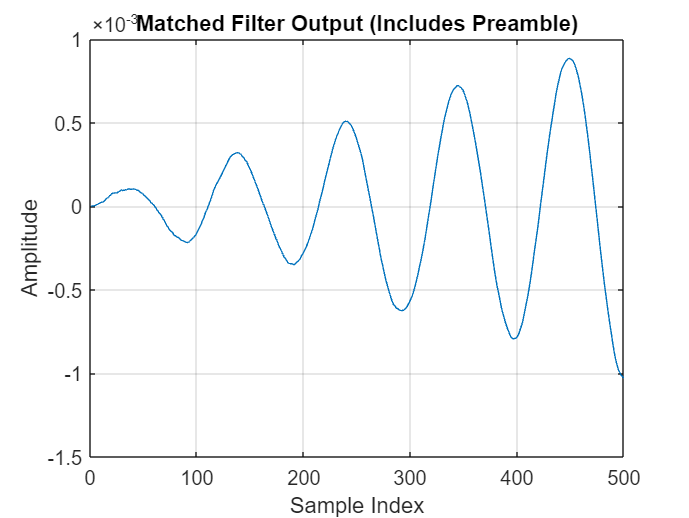

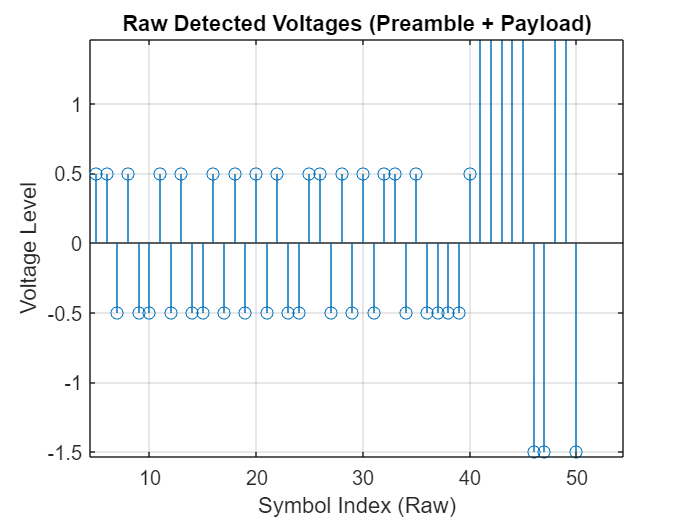

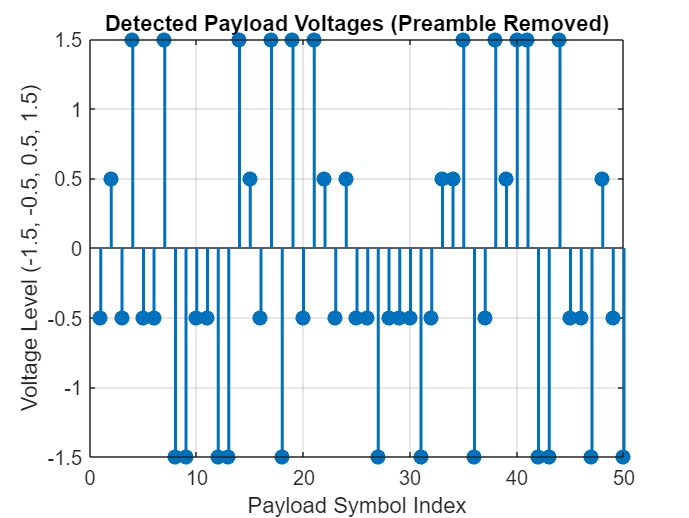

Symbol Error Rate (SER): 0.00001 (1 errors / 100000 symbols)



Payload Check (First 15):


Tx: [1 2 1 3 1 1 3 0 0 1 1 0 0 3 2]


Rx: [1 2 1 3 1 1 3 0 0 1 1 0 0 3 2]



if delay_start >= 0
    % --- B. Payload Extraction ---
    % Calculate where the payload should start
    % Start Index = (Delay) + (Length of Preamble) + 1
    payload_start_idx = delay_start + preamble_len + 1;
    payload_end_idx = payload_start_idx + payload_len - 1;
    rx.plot_all_separate(payload_start_idx);
    % Check bounds to avoid errors if the frame is cut off
    if payload_end_idx <= length(rx_seq)
        
        % Extract the received payload
        rx_payload = rx_seq(payload_start_idx : payload_end_idx);
        
        % --- C. Error Calculation ---
        % Compare Transmitted Payload vs Received Payload
        errors = sum(payload ~= rx_payload);
        SER = errors / length(payload);
        
        fprintf('Symbol Error Rate (SER): %.5f (%d errors / %d symbols)\n', ...
            SER, errors, length(payload));
        
        if SER == 0
            disp('SUCCESS: Preamble Sync & Data Recovery successful.');
        end
        
        % Visual Verification (First 15 symbols of Payload)
        fprintf('\nPayload Check (First 15):\n');
        fprintf('Tx: %s\n', mat2str(payload(1:15)));
        fprintf('Rx: %s\n', mat2str(rx_payload(1:15)));
        
    else
        disp('Error: Frame end not received (Delay too large or simulation too short).');
    end
else
    rx.plot_all_separate();
    disp('Error: Preamble not found (Negative delay). Check SNR or Filters.');
end

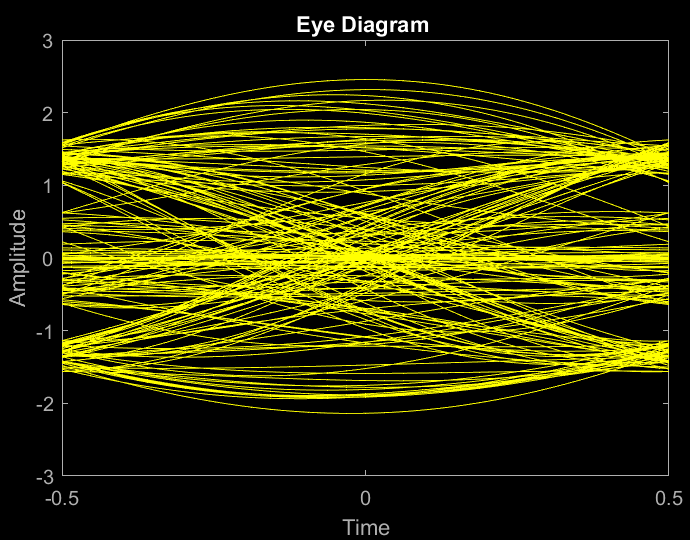

eyediagram(rx.matched(100:12000), rx.Ns);